# `'donutPlot.m' `in MATLAB

`Author: Connor Gallimore`

`Original: 12/26/2023`

`Modified: 11/20/2024`

Let's make some fictitious data representing proportions for different groups / subjects.

data= [0.2445	0.2554	0.3237	0.1762;
       0.1924	0.2255	0.1672	0.4147;
       0.1513	0.2769	0.2749	0.2967;
       0.1402	0.3639	0.2439	0.2518]; 

total= sum(data, 2); 

We can see that the columns correspond to the different components of the whole, whereas the groups / subjects lie along the rows.

## The standard pie chart

Let's plot all 4 sets of proportions from left-to-right on the same plot. The native` 'pie.m' `accepts vector input, so we'll need 4 calls.

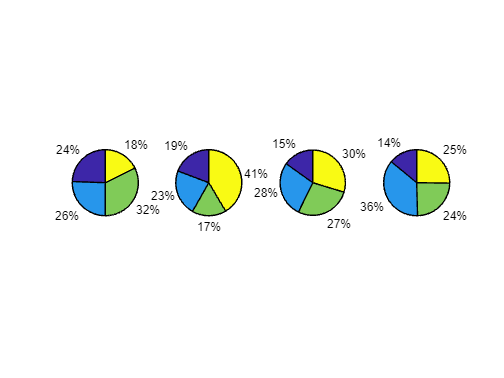

n_subj= size(data, 1); 

figure;
for s= 1:n_subj
    subplot(1, n_subj, s);
    pie(data(s, :));
end

## `'donutPlot.m' `reproduces this using circular arcs instead

However,` 'donutPlot.m' `was designed to handle matrix input by specifying the dimension that individual components of your proportions lie. Here, since each row is a different "group", and each column contains the constituents of the group, we specify '2'.

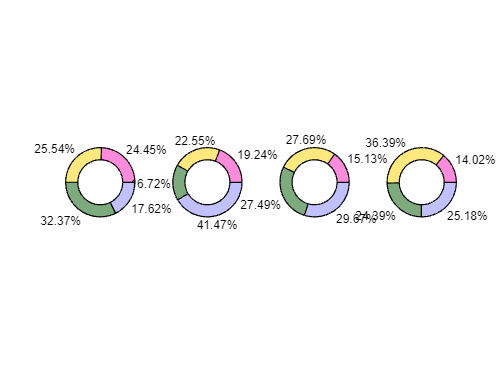

figure;
donutPlot(data);

For vector input, dimension is optional, and in general dimension is optional, defaulting to` 2 `as above, but can be specified as` 1 `for a transposed input (column = group, rows = components).

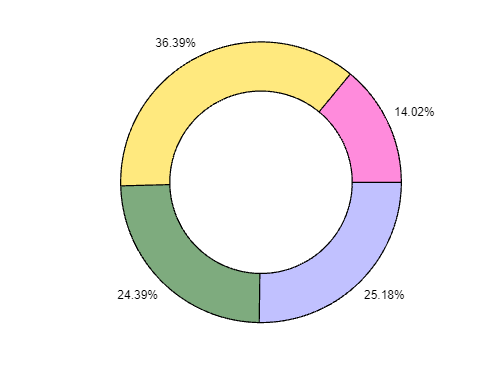

ans = struct with fields:
     arcH: [1×1 struct]
     txtH: [1×1 struct]
    color: [4×3 double]


figure; 
donutPlot(data(4, :))

## Storing output as a variable

Notice no semicolon suppression shows a structure of handles to the 1) arcs, 2) text, and 3) colors used in the plot elements is returned, which can be assigned to a variable for later access of these properties. 

figure;
h= donutPlot(data, 2);

## Orientation customization

Notice that by default, for matrix input, plotting orientation is horizontal. Though you can indicate vertical plotting using the` 'orientation' `flag as a Name,Value pair.

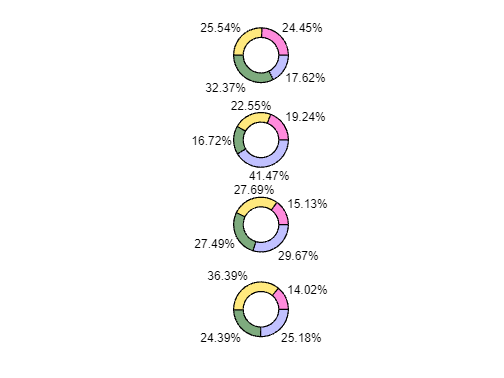

figure;
donutPlot(data, 2, 'orientation', 'vertical');

You can also use a third` 'concentric' `option, which produces concentric circles from inside to outside. 

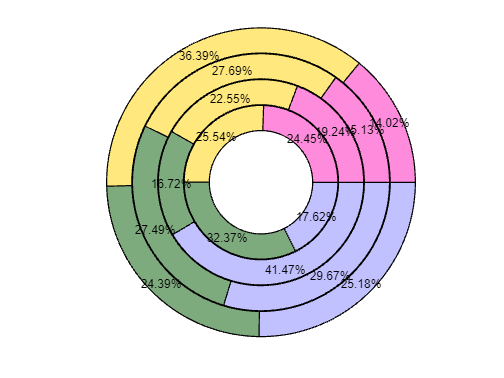

figure;
donutPlot(data, 2, 'orientation', 'concentric');

All of these options support a shorthand specification as well by using `'h'`, `'v'`, or `'c'` for the corresponding above inputs. 

## Altering the inner radius

The` 'innerRadius' `Name,Value pair (case insensitive; as are all following) specifies the inner radius of the donut as a proportion of the outer radius. This means you can plot a simple pie chart with input '0', and invisible rings with input '1'. The default is '0.65'. Plot one subject's data for simplicity.

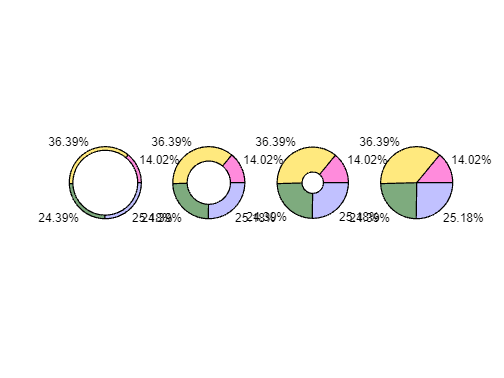

r= 0.9:-0.3:0; 

figure;  
for s= 1:n_subj
    subplot(1, n_subj, s)
    donutPlot(data(4, :), 'innerRadius', r(s));
end

Here, you have to use a loop because the function currently only supports a scalar, common radius applied to all groups in the case of matrix input.

## Start angle customization & text precision

The` 'startAngle' `Name,Value pair allows specification of the position where all patches for the first component emanate. Positions correspond to the unit circle, so the default '0' is 3 o'clock, and '90' is midnight. Positive angles step counter-clockwise, whereas negative angles will step clockwise. We'll add on the `'precision'` pair here to to specify the max decimal place reported, cleaning up the text a bit. 

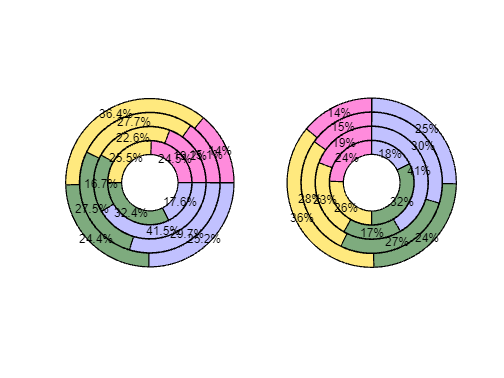

figure;  
subplot(1, 2, 1)
donutPlot(data, 2, 'orientation', 'c', 'precision', 1);
subplot(1, 2, 2)
donutPlot(data, 2, 'startangle', 90, 'orientation', 'c', 'precision', 0);

## Line and color specification

Conforms to the same specs used by default in MATLAB for `'edgeColor'`, `'lineWidth'`, `'textColor'`. I introduce these separately from `'faceColor'` (below) because these 3 receive one argument which is applied to all patch or text elements, whereas `'faceColor'` can receive a 1-to-1 mapping for all patch element faces (i.e. vector or matrix input).

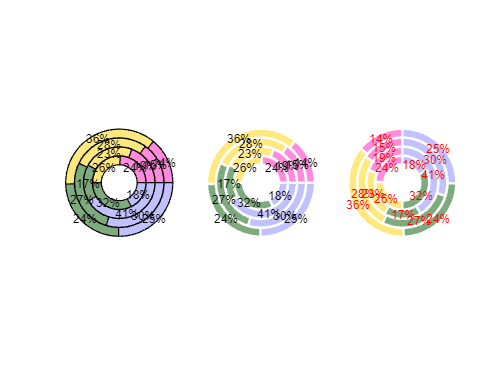

figure;  
subplot(1, 3, 1)
donutPlot(data, 2, 'orientation', 'c', 'precision', 0);
subplot(1, 3, 2)
donutPlot(data, 2, 'orientation', 'c', 'edgecolor', 'w', 'linewidth', 2, 'precision', 0);
subplot(1, 3, 3)
donutPlot(data, 2, 'orientation', 'c', 'edgecolor', [1 1 1], 'linewidth', 2, 'textcolor', 'r', 'startangle', 90, 'precision', 0);

## Facecolor customization

This function utilizes` 'distinguishable_colors.m' `(https://www.mathworks.com/matlabcentral/fileexchange/29702-generate-maximally-perceptually-distinct-colors) to create colors for you, though you are free to pass your own custom color arguments in using` 'facecolor' `followed by an m x 3 array input, where` m == size(data, 1)`

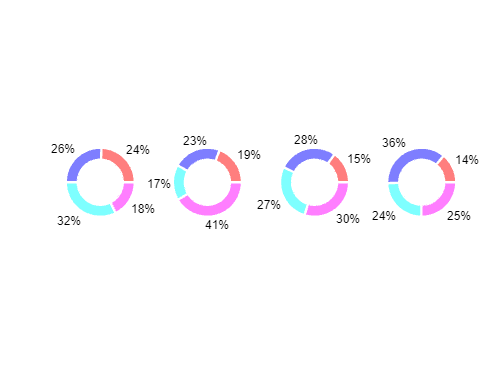

simple_colrs= [1 0 0;
              0 0 1;
              0 1 1;
              1 0 1];
figure;
donutPlot(data, 2, 'facecolor', simple_colrs, 'precision', 0, 'edgecolor', 'w', 'linewidth', 2);

## Color scheme

By default, the colors are assigned to the categories (i.e. the various components making up the totals for each group). However, you can alter the color scheme to assign the different colors to each data series, which darkens the custom input (or default) colors for the subsequent components.

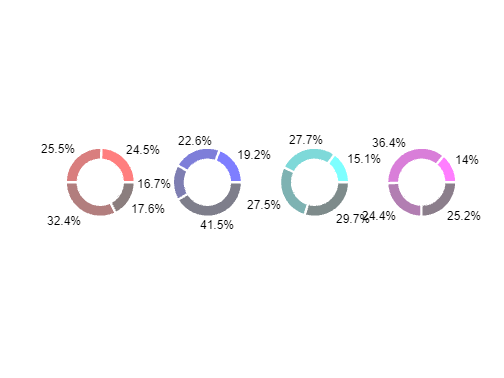

figure;
donutPlot(data, 2, 'scheme', 'series', 'facecolor', simple_colrs, 'precision', 1, 'edgecolor', 'w', 'linewidth', 2);

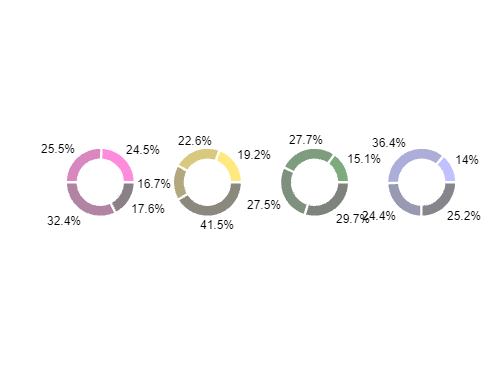


% see also the default colors with the series 'scheme'

figure;
donutPlot(data, 2, 'scheme', 'series', 'precision', 1, 'edgecolor', 'w', 'linewidth', 2);

## Usage with colormaps (MATLAB default or custom)

Version `2.0.0` uses `'FaceVertexCData'` to alter patch color, meaning it can also directly be assigned a value for usage with default colormaps

Note to self: Make facealpha compatible with vector input

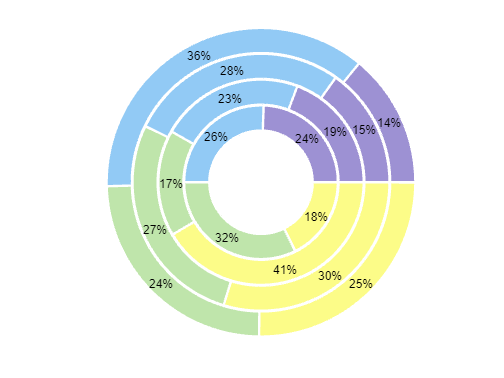

figure;
donutPlot(data, 2, 'orientation', 'c', 'facecolor', 1:4, 'edgecolor', 'w', 'linewidth', 2, 'precision', 0);

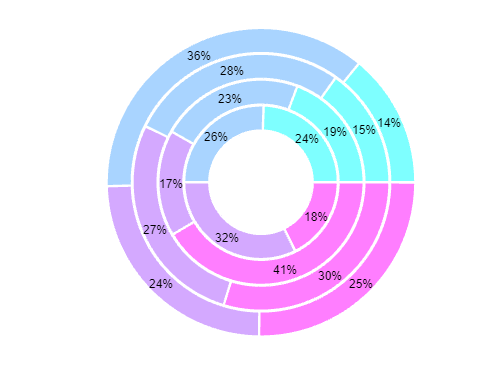

figure;
donutPlot(data, 2, 'orientation', 'c', 'facecolor', 1:4, 'edgecolor', 'w', 'linewidth', 2, 'precision', 0);
colormap(cool)

## Multiple colormaps for each plot

Here's just one of many ways you could do this. I did it this way to use 4 different default colormaps, one for each plot.

NOTE: if plotting subsequent plots 1 at a time as in this example, i recommend *decreasing* the default radius size (default `r= 3`) using the name value pair `'radius'`. This is because the function has been written to scale radius differently if specifying 1 plot (vector input) as opposed to multiple (matrix input). Decreasing the size will keep it readable.

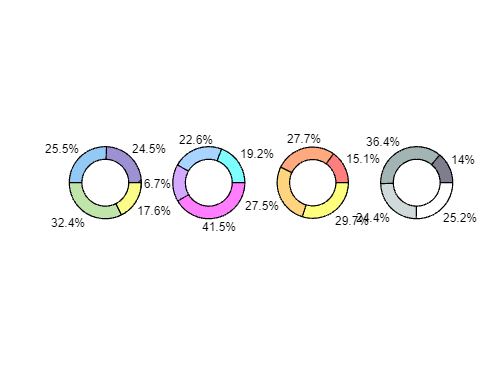

n_comps= size(data, 2);

cmaps= cat(3, parula(n_comps), cool(n_comps), autumn(n_comps), bone(n_comps)); 

figure;
for s= 1:n_subj
    subplot(1, n_subj, s);
    donutPlot(data(s, :), 'facecolor', cmaps(:, :, s), 'precision', 1);
end

You can also use this same strategy with` subplot() `and altering` 'radius' `to experiment with different grid arrangements

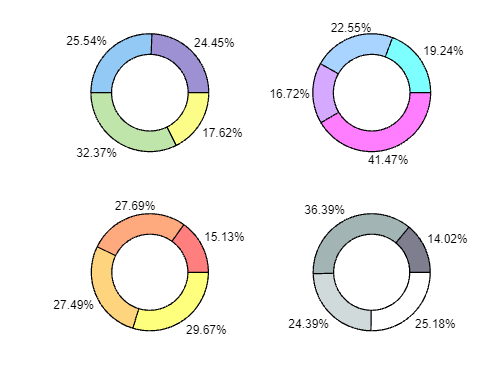

figure;
for s= 1:n_subj
    subplot(2, n_subj/2, s);
    donutPlot(data(s, :), 2, 'facecolor', cmaps(:, :, s));
end

## Recommended usage with legend()

A basic, empty '`legend()`' call will produce an unwieldy display of all patches which redundantly repeat the same colors used across all series.  We can truncate this by editing our legend call to ignore remaining entries (by passing an empty string) and only plot those common to multiple data series. Anyone who's used a legend in MATLAB with '`pie.m`' knows that its default location will likely obscure the data.  We can use the `'Position'` property to achieve a cleaner look

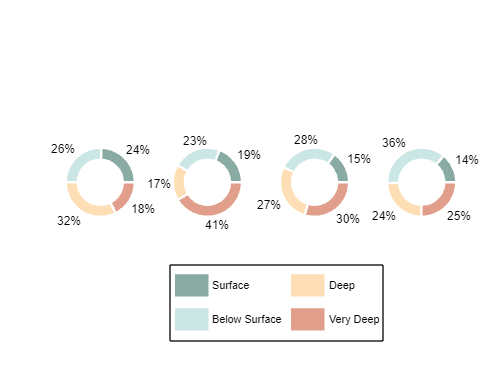

lgd_pad= numel(data) - size(data, 2); 
lgd_txt= ["Surface", "Below Surface", "Deep", "Very Deep", strings(1, lgd_pad)];

figure;
donutPlot(data, 2, 'facecolor', 1:4, 'edgecolor', 'w', 'linewidth', 2, 'precision', 0);
colormap(owt)
legend(lgd_txt, "NumColumns", 2, "Position", [0.5 0.1 0.1 0.2])

Alternatively, see the vertical style:

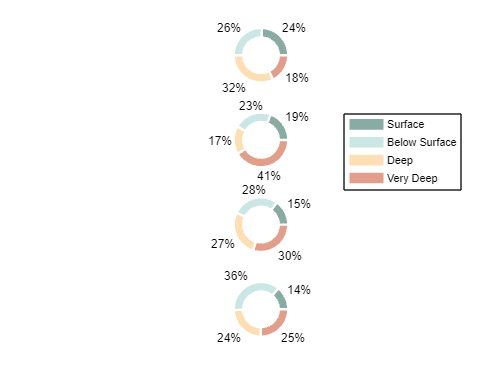

figure;
donutPlot(data, 2, 'orientation', 'v', 'facecolor', 1:4, 'edgecolor', 'w', 'linewidth', 2, 'precision', 0);
colormap(owt)
legend(lgd_txt, "Position", [0.75 0.5 0.1 0.2])

And the concentric style:

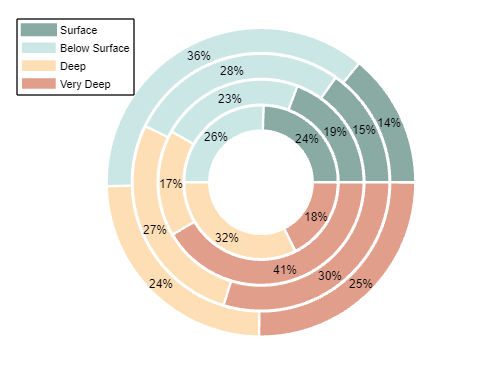

figure;
donutPlot(data, 2, 'orientation', 'c', 'facecolor', 1:4, 'edgecolor', 'w', 'linewidth', 2, 'precision', 0);
colormap(owt)
legend(lgd_txt, "Position", [0.1 0.75 0.1 0.2])

You can also use the '`newline`' formalism in versions 2016b and after to 'return' long legend labels:

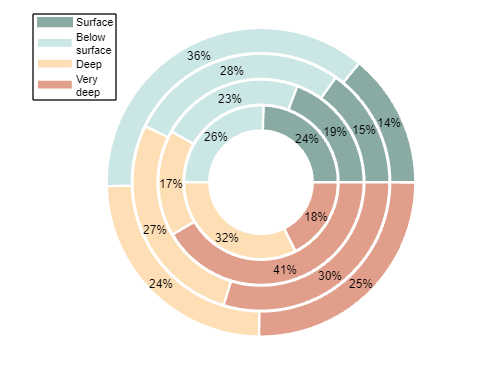

lgd_txt2= [{"Surface", ...
            strcat("Below", string(newline), "surface"), ...
            "Deep", ...
            strcat("Very", string(newline), "deep")}, ...
            strings(1, lgd_pad)];   % dont forget to pad


figure;
donutPlot(data, 2, 'orientation', 'c', 'facecolor', 1:4, 'edgecolor', 'w', 'linewidth', 2, 'precision', 0);
colormap(owt)
legend(lgd_txt2, "Position", [0.1 0.75 0.1 0.2])

## Zero handling

The function is also capable of handling zeros in one or more of your components. Let's alter our original data matrix to demonstrate this. Notice now that the components in series 1 and 4 dont sum to one. In this case, the function produces a partial arc, as` 'pie.m' `does.

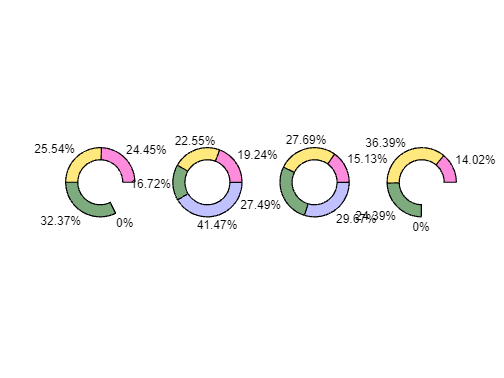

data2= [0.2445	0.2554	0.3237	0;
        0.1924	0.2255	0.1672	0.4147;
        0.1513	0.2769	0.2749	0.2967;
        0.1402	0.3639	0.2439	0]; 

figure;
donutPlot(data2, 2);

## Zero handling II

In the event your data has a 0% component, but the series still sums to 1 (proportions) or 100 (percentages), the function omits this component, as does` 'pie.m'`. In this situation, '`donutPlot()`' invokes a special case which plots the data as a '`polyshape()`' object, producing a complete donut which lacks that pesky, tiny '0%' component sliver. Compare the two: 

data3= [100 0];
% alternatively, try 
% data3= [34 33 33 0];

figure;
subplot(1, 2, 1)
donutPlot(data3, 2);

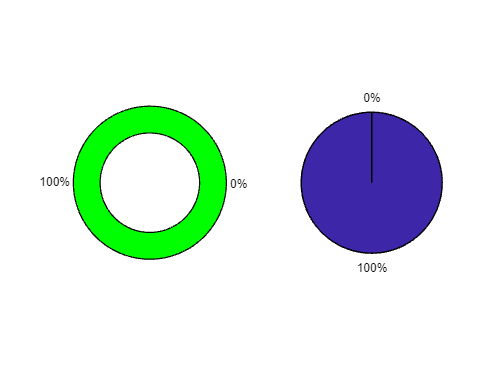


subplot(1, 2, 2)
pie(data3)

## Zero handling III

The zero doesnt have to be in the last position... Zeroing the second component of series 1 and 4 omits the second category. 

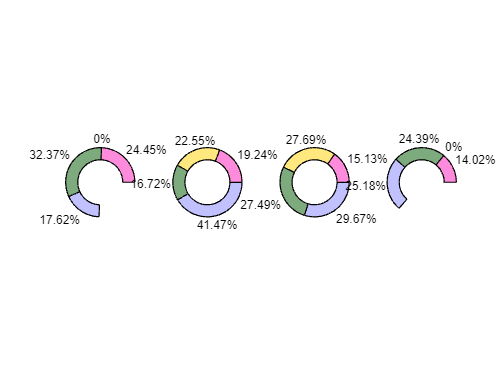

data4= [0.2445	0	0.3237	0.1762;
       0.1924	0.2255	0.1672	0.4147;
       0.1513	0.2769	0.2749	0.2967;
       0.1402	0	0.2439	0.2518]; 

figure;
donutPlot(data4, 2);

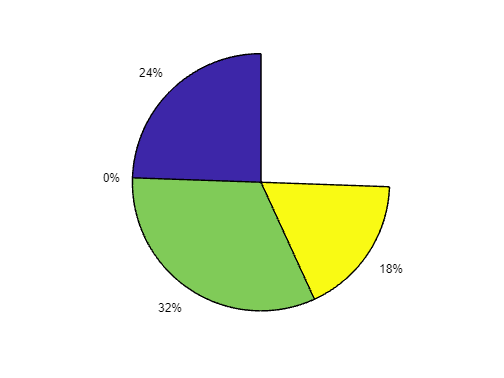


figure; pie(data4(1, :))

## Zero handling IV

... or in the same position across consecutive series.

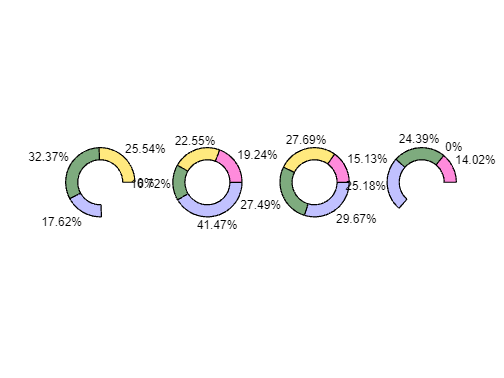

data5= [0	0.2554	0.3237	0.1762;
       0.1924	0.2255	0.1672	0.4147;
       0.1513	0.2769	0.2749	0.2967;
       0.1402	0	0.2439	0.2518]; 

figure;
donutPlot(data5, 2);

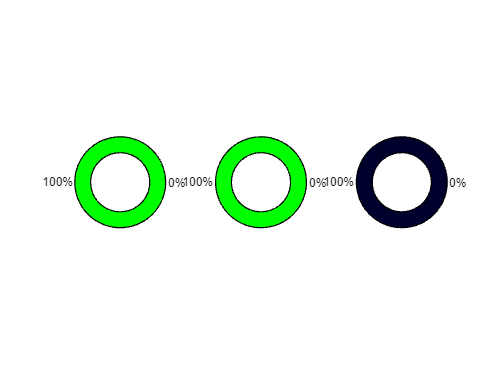


data6= [data3; data3; 0 100];

figure;
donutPlot(data6, 2);

## Fully loaded plot call

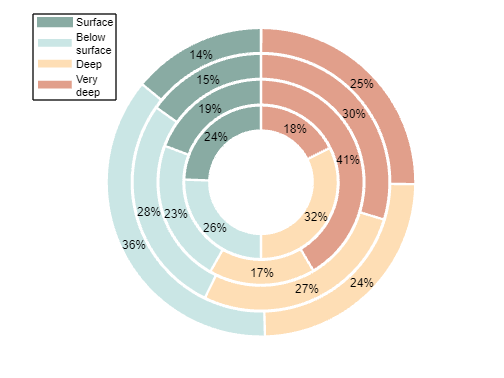

figure; 
donutPlot(data, 2, 'orientation', 'c', 'precision', 0, 'facecolor', 1:4, 'edgecolor', 'w', 'linewidth', 2, 'startangle', 90);
colormap(owt)
legend(lgd_txt2, "Position", [0.1 0.75 0.1 0.2])

## Local functions

My favorite colormap.

function map = owt(m)

if nargin < 1, m = size(get(gcf,'colormap'), 1); end


values = flipud( [0.7686 0.2588	0.1019;
                  0.9764 0.5607	0.2705;
                  0.9960 0.7490	0.4313;
                     1      1      1;
                  0.5921 0.8078	0.8000;
                  0.0705 0.5647	0.5568;
                  0.0862 0.3490	0.2901] );

P = size(values, 1);
map = interp1(1:P, values, linspace(1, P, m), 'linear');
end